cdata = [trainChunk'];
grp = [trainGs'];

c = cvpartition(length(grp),'KFold',10);

sigma = optimizableVariable('sigma',[1e-5,1e5],'Transform','log');
box = optimizableVariable('box',[1e-5,1e5],'Transform','log');
Nu=optimizableVariable('Nu',[0,1]);

minfn = @(z)kfoldLoss(fitcsvm(cdata,grp,'CVPartition',c,...
    'KernelFunction','linear','BoxConstraint',z.box,...
    'KernelScale',z.sigma,'Nu',z.Nu));

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        sigma |          box |           Nu |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.48798 |      1139.2 |     0.48798 |     0.48798 |   0.00027687 |     0.011869 |      0.57173 |
|    2 | Best   |     0.45815 |        1272 |     0.45815 |     0.45815 |      0.57206 |         1204 |     0.062492 |
|    3 | Accept |     0.49981 |      11.379 |     0.45815 |     0.45815 |       131.42 |   2.4733e-05 |       0.9127 |
|    4 | Accept |     0.49415 |      1363.7 |     0.45815 |     0.45815 |    5.514e-05 |        15070 |      0.93806 |
|    5 | Best   |     0.42756 |      11.185 |   

results =   BayesianOptimization with properties:

                      ObjectiveFcn: @(z)kfoldLoss(fitcsvm(cdata,grp,'CVPartition',c,'KernelFunction','linear','BoxConstraint',z.box,'KernelScale',z.sigma,'Nu',z.Nu))
              VariableDescriptions: [1×3 optimizableVariable]
                           Options: [1×1 struct]
                      MinObjective: 0.4211
                   XAtMinObjective: [1×3 table]
             MinEstimatedObjective: 0.4211
          XAtMinEstimatedObjective: [1×3 table]
           NumObjectiveEvaluations: 30
                  TotalElapsedTime: 1.2687e+04
                         NextPoint: [1×3 table]
                            XTrace: [30×3 table]
                    ObjectiveTrace: [30×1 double]
                  ConstraintsTrace: []
                     UserDataTrace: {30×1 cell}
      ObjectiveEvaluationTimeTrace: [30×1 double]
                IterationTimeTrace: [30×1 d

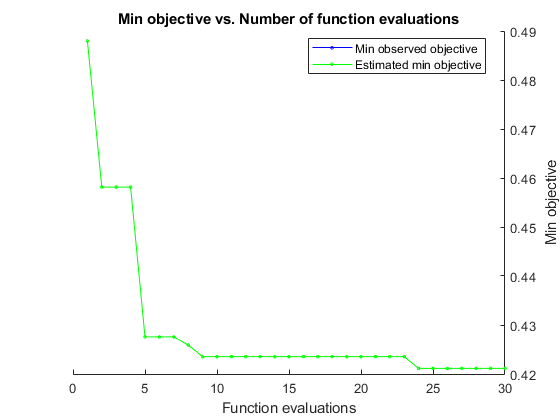

tic
results = bayesopt(minfn,[sigma,box,Nu],'IsObjectiveDeterministic',true,...
    'AcquisitionFunctionName','expected-improvement-plus')

toc

Elapsed time is 12687.200719 seconds.


z(1) = results.XAtMinObjective.sigma;
z(2) = results.XAtMinObjective.box;
SVMModel = fitcsvm(cdata,grp,'KernelFunction','rbf',...
    'KernelScale',z(1),'BoxConstraint',z(2));

[Labels, Scores]=predict(SVMModel,testChunk');
numCorrect=find(Labels==testGs');
CorrectTest(uu,yy)=length(numCorrect)/length(testGs);